# Dynamic simulation using complementarity methods

Author: Jiayin Xie

Date: July 14 2020

## Introduction to the PATH solver

The Path solver is a newton-based solver for mixed complementarity problems (MCP). Our dynamic model is formulated as MCP, so it can be solved by PATH.

Let $l\in R^{n\;}$be the vector of lower bounds,  $u\in R^{n\;}$ be the vector of upper bounds, and $l<u$. $n$ is the number of equations and unknown variables. Let $B:=\left\lbrace z\in R^n |l\le z\le u\right\rbrace$ and $F:B\to R^n$. The vector $z\in B$ is a solution to MCP $\left(F,B\right)$, if and only if the following holds for each $i\in \left\lbrace 1,\ldotp \ldotp \ldotp ,n\right\rbrace :$


$$\begin{array}{l}
l_{i\;} \le z_i \le u_i \;\;\mathrm{and}\;F_i \left(z\right)=0\\
z_i =l_i \;\mathrm{and}\;F_i \left(z\right)>0\\
z_i =u_i \;\mathrm{and}\;F_i \left(z\right)<0
\end{array}$$
  

### The function 'pathmcp' 

 [z,f,J,mu,status] = pathmcp(z,l,u,cpfj,A,b,t,mu)

Inputs:

- z - Initial guess (colum vector)

- l - lower bound vectors. u - upper bound vectors. For equation f(i) = 0,  l(i) = -inf, u(i) - inf.  For compelmentarity problem 0<=z(i)*f(i) >= 0,  l(i) = 0, u(i)>=0.

- cpfj - the name of the m-file for evaluating the function f and its Jacobian J.

Outputs:

- z - solution

- f,J - evaluations

- status - 1 for success and 0 for fail

### Interface:

%% notation
% l - beginning of current time step
% l+1 - end of current time step
% If the error 'Jacobian has too many entries: update nnz in pathmcp.m'
% appears , you can modify the mod_N parameter in pathmcp.m file

clear all
cd('..');
addpath('convex_contact_patches_interface');
addpath('visualize');
addpath('utility');
addpath('funjac');
addpath('pathmexmaci64');

cd('convex_contact_patches_interface')
A = struct();

% mass of the object
A.mass = 3; %(kg)
A.gravity = 9.8; %(m/s^2)

% approximate dimension of the object 
%A.dim=[0.5 0.5 0.5]; %(m) length width height

% friction model
A.ellipsoid = [1 1 0.1]; 
A.cof = 0.22;

% time step
A.h = 0.01; %(s)

% initial state and configuration
A.initial_q = [0;0;2]; % m
A.initial_v = [1;1;0];  %m/s

% unit
A.unit = 1; % 1 - m, 10 - dm, 100 - cm, 1000 - mm  

% impulses
A = planner_point(A);

% loops
A = NCP_point(A);

movie_point(A);


### Loops:

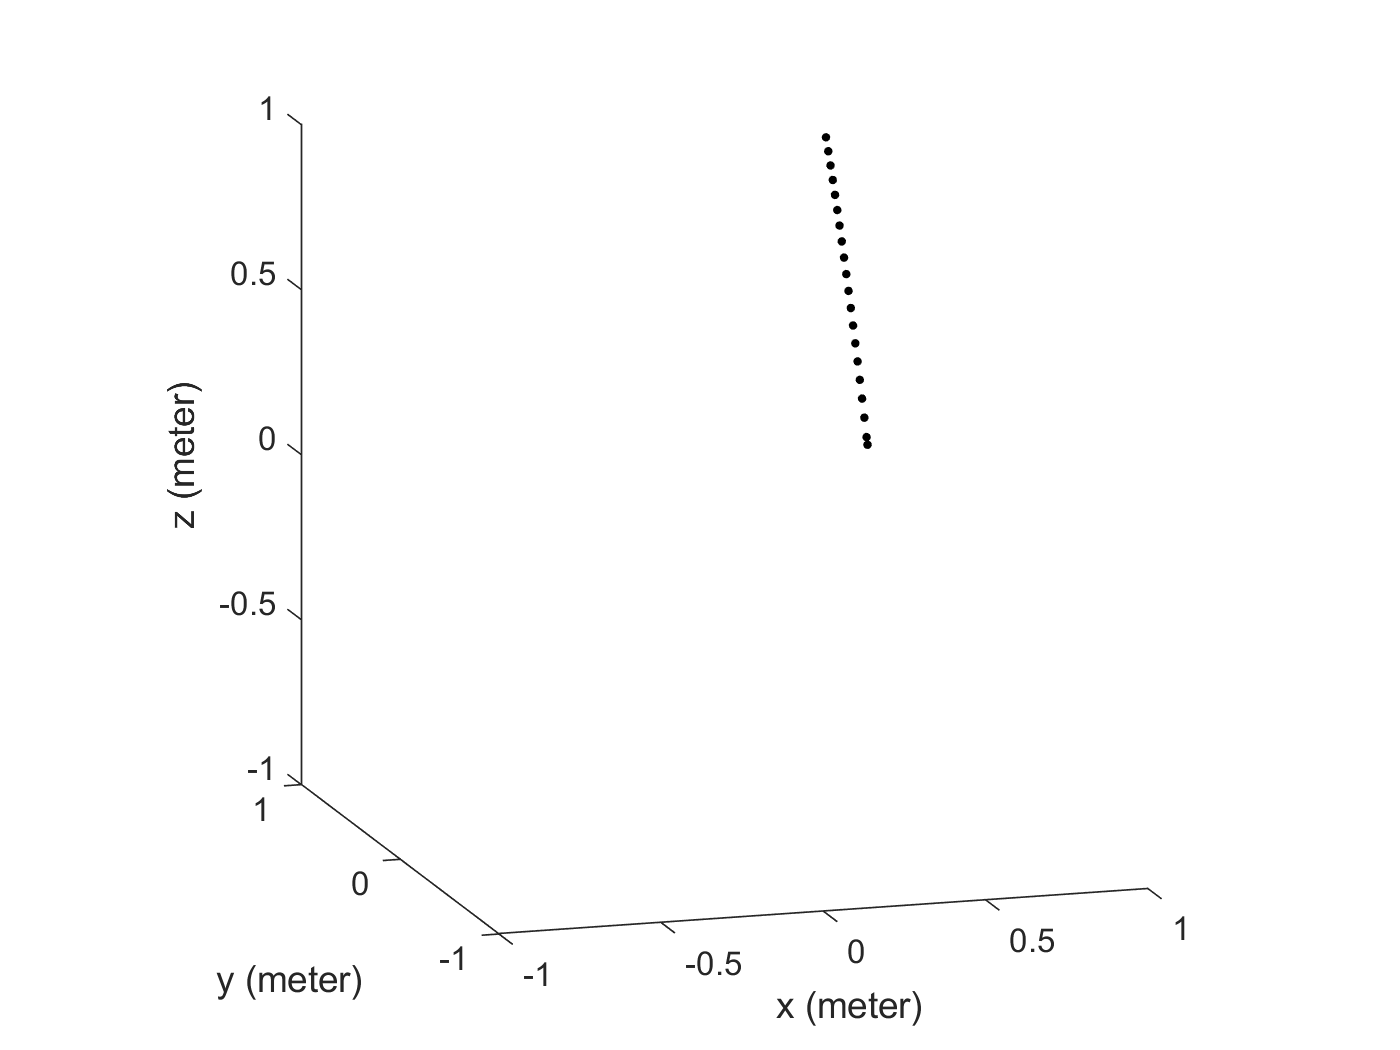

function A = NCP_point(A)
unit = A.unit;
N = A.N;


global e_t e_o mu;

e_t = A.ellipsoid(1);
e_o = A.ellipsoid(2);
mu =A.cof;


global m g;
m = A.mass;

g = A.gravity*unit;

% global len wid heg I_xx I_yy I_zz;
% 
% len = A.dim(1)*unit;  % in fixed body frame's x direction
% wid = A.dim(2)*unit;  % in fixed body frame's y direction
% heg = A.dim(3)*unit;  % in fixed body frame's z direction
% 
% I_xx = (m/12)*(wid^2+heg^2);
% I_yy = (m/12)*(len^2+heg^2);
% I_zz = (m/12)*(len^2+wid^2);

global h;
h = 0.01;

% applied wrenches

global p_x p_y p_z p_xt p_yt p_zt;
p_x = 0;
p_y = 0;
p_z = 0;
% p_xt = 0;
% p_yt = 0;
% p_zt = 0;

%% initial configuration and state
% q_old - position and orientation vector at l, q_old=[q_xo;q_yo;q_zo;q0_o;q1_o;q2_o;q3_o]
global q_old;

q_old(1:3,1) = A.initial_q(1:3)*unit;
%q_old(4:7,1) = A.initial_q(4:7);
% nu_old - generalized velocity vector at l, nu_old=[v_xo;v_yo;v_zo;w_xo;w_yo;w_zo]
global nu_old;

nu_old(1:3,1) = A.initial_v(1:3)*unit;
%nu_old(4:6,1) = A.initial_v(4:6); 


%% define the infinity and initial guess and fun to use
 A = initial_guess(A);
 l = A.l;
 u = A.u;
 Z = A.Z;

%% cpfj file
fun = 'mcp_funjac_point';

for i=1:N
    
    tic;
    [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
    time_NCP = toc;
    if status == 1 
        A.time_NCP(i) = time_NCP;
    else
        A.time_NCP(i) = 0;
    end
    j = 1;
    if i == 1
        while status == 0
        j = j+1;
        Z = change_initial_guess(A,Z);
        tic
        [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
        time_NCP = toc;
        if status == 1 
            A.time_NCP(i) = time_NCP;
        else
            A.time_NCP(i) = 0;
        end
            if j>=30
                error('Path can not found the solution, change your initial guess');
            end
        end
        
    else
        while status == 0
            j = j+1;
            Z = change_guess(A,Z,Q);
            tic
            [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
            time_NCP = toc;
            if status == 1 
                A.time_NCP(i) = time_NCP;
            else
                A.time_NCP(i) = 0;
            end
            if j>=30
                error('Path can not found the solution, change your initial guess');
            end
        end
    end
    
   

   [Q,Nu] = kinematic_map(q_old,A.z(:,i),h); % the function which returns the configuration and velocity of object
   
   Z = A.z(:,i); % updating the initial guess for each iteration
   A.q(:,i) = Q; 
   
  

   q_old = Q; % updating the beginning value for next time step
   nu_old = Nu; 
   
   
end

end

### One example for cpfj file: 'mcp_funjac_point'

function [F, J, domerr] = mcp_funjac_point(z, jacflag)

%% initialize
z = z(:);
F = [];
J = [];
domerr = 0;

%% obtain value of global variables
global h;

global q_old ;
q_xo = q_old(1);
q_yo = q_old(2);
q_zo = q_old(3);

global nu_old;
v_xo =nu_old(1);
v_yo =nu_old(2);
v_zo =nu_old(3);

global m mu e_o e_t g;

global p_x p_y p_z;

%% unknown variables

v_x = z(1);
v_y = z(2);
v_z = z(3);

p_t = z(4);
p_o = z(5);

sig = z(6);
p_n = z(7);


%% intermediate variables appear in the chain rule
% z - vector of unknown variables 

% The intermediate variables are:
% 1. [qo(z) q1(z) q2(z) q3(z)] - Quaternions, which depends on z
% 2. Rij(qo,q1,q2,q3) - elements in rotation matrix, which depends on the quaternion
% 3. Iij(qo,q1,q2,q3) - elements in RIR', which depends on the quaternion
% 4. q_x(z),q_y(z),q_z(z) - position vector in l+1, which depends on q_old and z

% Thus system of equations F can be described by the unknown variables z or
% with intermediate variables:
% 1. F(z,Rij,Iij,q_x,q_y,q_z) - F descriabed by z with intermediate variables
% 2. F(z) - F described by unknown variables z

% Based on the chain rule, Jocobain J = J1*J2*J3 where:
% J - dF(z)/dz Jacobian matrix 
% J1 = dF(z,Rij,Iij,q_x,q_y,q_z)/d[z,Rij,Iij,q_x,q_y,q_z] 
% J2 = d[z,Rij(qo,q1,q2,q3),Iij(qo,q1,q2,q3),q_x(z),q_y(z),q_z(z)]/d[z,qo,q1,q2,q3] 
% J3 = d[z,qo(z),q1(z),q2(z),q3(z)]/dz 

% q0 = -(2*((h*q1_o*w_x)/2 - q0_o + (h*q2_o*w_y)/2 + (h*q3_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q1 = (2*(q1_o + (h*q0_o*w_x)/2 + (h*q3_o*w_y)/2 - (h*q2_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q2 = (2*(q2_o - (h*q3_o*w_x)/2 + (h*q0_o*w_y)/2 + (h*q1_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q3 = (2*(q3_o + (h*q2_o*w_x)/2 - (h*q1_o*w_y)/2 + (h*q0_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);

q_x = q_xo+h*v_x;
q_y = q_yo+h*v_y;
q_z = q_zo+h*v_z;

% R11 = q0^2 + q1^2 - q2^2 - q3^2;
% R12 = 2*q1*q2 - 2*q0*q3;
% R13 = 2*q0*q2 + 2*q1*q3;
% R21 = 2*q0*q3 + 2*q1*q2;
% R22 = q0^2 - q1^2 + q2^2 - q3^2;
% R23 = 2*q2*q3 - 2*q0*q1;
% R31 = 2*q1*q3 - 2*q0*q2;
% R32 = 2*q0*q1 + 2*q2*q3;
% R33 = q0^2 - q1^2 - q2^2 + q3^2;
% 
% I11 = I_xx*R11^2 + I_yy*R12^2 + I_zz*R13^2;
% I12 = I_xx*R21*R11 + I_yy* R22*R12 + I_zz*R23*R13;
% I13 = I_xx*R31*R11 + I_yy* R32*R12 + I_zz*R33*R13;
% I21 = I12;
% I22 = I_xx*R21^2 + I_yy*R22^2 + I_zz*R23^2;
% I23 = I_xx*R31*R21 + I_yy*R32*R22 + I_zz*R33*R23;
% I31 = I13;
% I32 = I23;
% I33 = I_xx*R31^2 + I_yy*R32^2 + I_zz*R33^2;

%% system of equations f(x) == 0
% Newton_Euler equations
F(1) = p_t + p_x - m*(v_x - v_xo);
F(2) = p_o + p_y - m*(v_y - v_yo);
F(3) = p_n + p_z - m*(v_z - v_zo) - g*h*m;


% Friction Model without complementarity equation

F(4) = p_t*sig + e_t^2*mu*p_n*v_x;
F(5) = p_o*sig + e_o^2*mu*p_n*v_y;

% contact constraints without complementarity equation


% complementarity equation in Friction Model
F(6) = mu^2*p_n^2 - p_t^2/e_t^2 - p_o^2/e_o^2;

% complementarity equations in contact constraints

% non-penetration 
F(7) = q_z;


%% Jacobian matrix (Using chain rules) dF/d[z,q_x,q_y,q_z]*d[z,q_x,q_y,q_z]/dz

if (jacflag)
    J1 = [-m 0 0 1 0 0 0 0 0 0;
          0 -m 0 0 1 0 0 0 0 0;
          0  0 -m 0 0 0 1 0 0 0;
          e_t^2*mu*p_n 0 0 sig 0 p_t e_t^2*mu*v_x 0 0 0;
          0 e_o^2*mu*p_n 0 0 sig p_o e_o^2*mu*v_y 0 0 0;
          0 0 0 -2*p_t/e_t^2 -2*p_o/e_o^2 0 2*mu^2*p_n 0 0 0;
          0 0 h 0 0 0 0 0 0 1];
      
     J2 = [eye(7);
          h 0 0 0 0 0 0;
          0 h 0 0 0 0 0;
          0 0 h 0 0 0 0];
      
      J = J1*J2;

    
end
end


### Options for PATH in 'path.opt'

%convergence_tolerance 1e-6;

### Useful resources and documents:

website:[http://pages.cs.wisc.edu/~ferris/path.html](http://pages.cs.wisc.edu/~ferris/path.html)

Latest documents: [https://www.gams.com/latest/docs/S_PATH.html](https://www.gams.com/latest/docs/S_PATH.html)

## Scenario 1: A cuboid and a horizontal plane

### Problem description:

### System of equations:

### Codes:

## Scenario 2: A cylinder and a horizontal plane

### Problem description:

### System of equations:

### Codes: